# Train Network for Image Regression

Load the sample data, which consists of synthetic images of handwritten digits. The third output contains the corresponding angles in degrees by which each image has been rotated.

Load the training images as 4-D arrays using `digitTrain4DArrayData`. The output `XTrain` is a 28-by-28-by-1-by-5000 array, where:

- 28 is the height and width of the images.

- 1 is the number of channels.

- 5000 is the number of synthetic images of handwritten digits.

`YTrain` contains the rotation angles in degrees.

[XTrain,~,YTrain] = digitTrain4DArrayData;
% XTrain = 28*28*1*5000(28*28的影像, 共5000組)
% YTrain = 5000*1(數值為影像旋轉的角度)

Display 20 random training images using `imshow`.

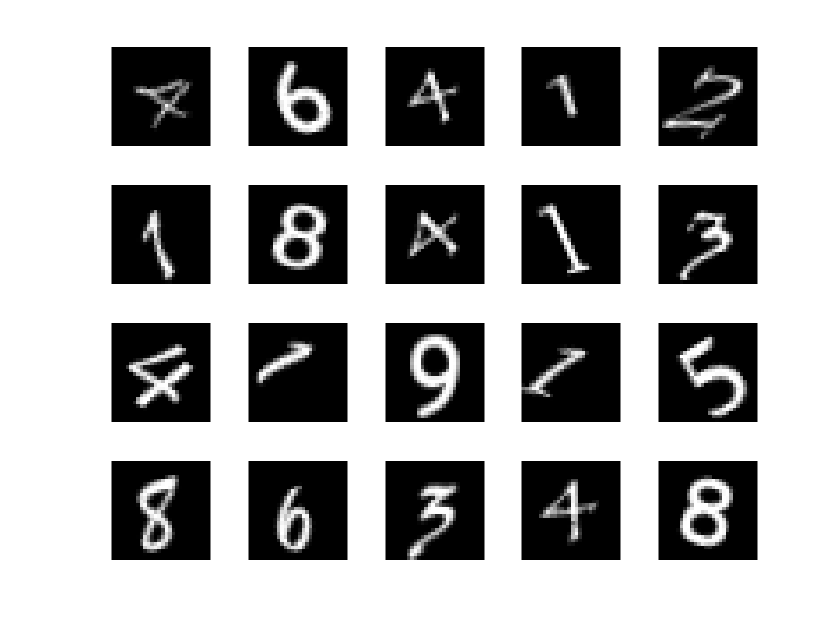

figure
numTrainImages = numel(YTrain); %5000
idx = randperm(numTrainImages,20);  %從numTrainImages(5000)中挑出20組data(不會重複)
for i = 1:numel(idx)
    subplot(4,5,i)  %畫一個4*5
    imshow(XTrain(:,:,:,idx(i)))
end

testing data

idx_test = randperm(size(XTrain, 4), 1000);  %1000為testing data
XTest = XTrain(:,:,:,idx_test);  %28*28*1*1000(新的label)
XTrain(:,:,:,idx_test) = [];  %28*28*1*4000(從28*28*1*5000中取出1000筆資料所以變成28*28*1*4000，空矩陣類似拿掉資料)
YTest = YTrain(idx_test);  %1000*1(新的label)
YTrain(idx_test) = [];  %4000*1(從5000*1中取出1000)

Specify the convolutional neural network architecture. For regression problems, include a regression layer at the end of the network.

layers = [ ...
    imageInputLayer([28 28 1])
    convolution2dLayer(12,25)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

Specify the network training options. Set the initial learn rate to 0.001.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the network.

net = trainNetwork(XTrain,YTrain,layers,options);

Test the performance of the network by evaluating the prediction accuracy of the test data. Use `predict` to predict the angles of rotation of the validation images.

YPred = predict(net,XTest);

Evaluate the performance of the model by calculating the root-mean-square error (RMSE) of the predicted and actual angles of rotation.

rmse = sqrt(mean((YTest - YPred).^2))

rmse = single
6.6694

validation data

idx_valid = randperm(size(XTrain, 4), 500);  %500為validation data
XValidation = XTrain(:,:,:,idx_valid);  %28*28*1*500(新的label)
XTrain(:,:,:,idx_valid) = [];  %28*28*1*3500(從28*28*1*4000中取出500筆資料所以變成28*28*1*3500，空矩陣類似拿掉資料)
YValidation = YTrain(idx_valid);  %500*1(新的label)
YTrain(idx_valid) = [];  %3500*1(從4000*1中取出500)

Train the network.

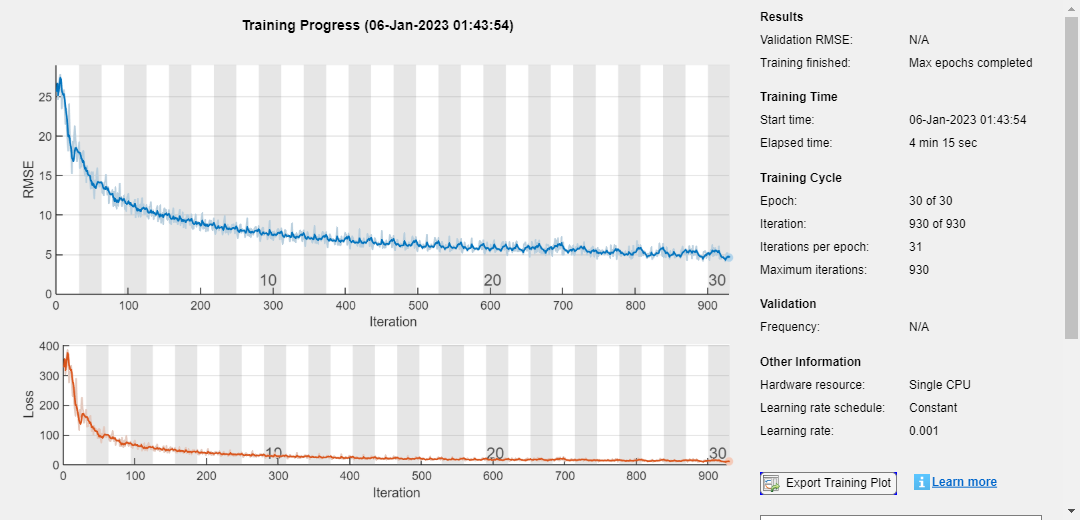

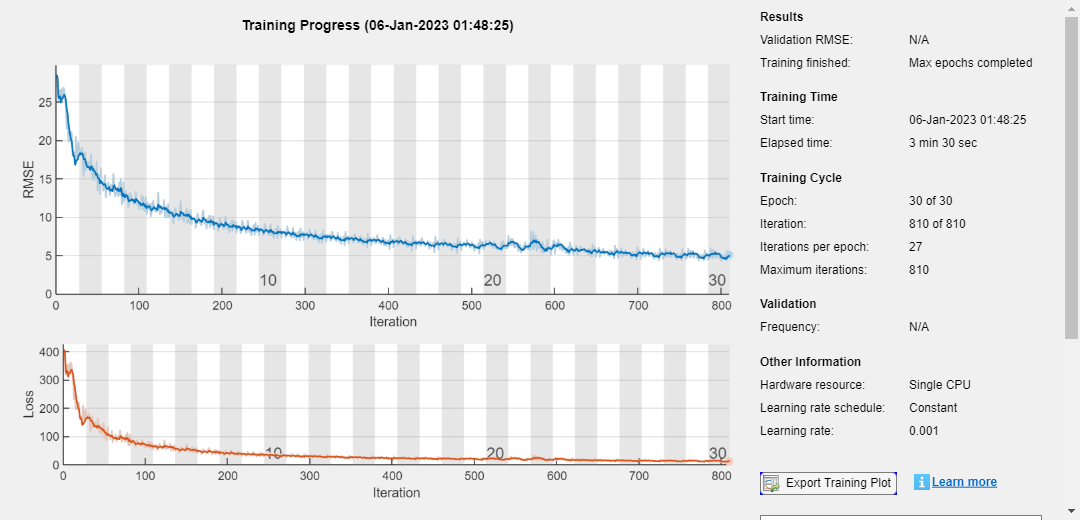

net = trainNetwork(XTrain,YTrain,layers,options);

Test the performance of the network by evaluating the prediction accuracy of the test data. Use `predict` to predict the angles of rotation of the validation images.

YPred = predict(net,XTest);

Evaluate the performance of the model by calculating the root-mean-square error (RMSE) of the predicted and actual angles of rotation.

rmse = sqrt(mean((YTest - YPred).^2))

rmse = single
6.9783

*Copyright 2012 The MathWorks, Inc.*